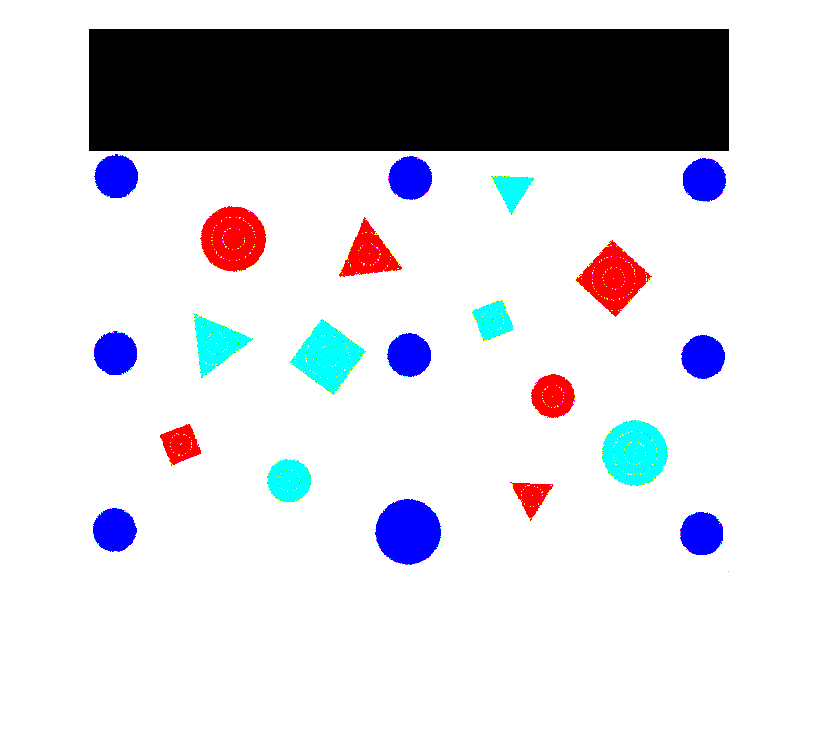

% sim = coppeliaRobot();


q = [0 -24 -21 45 0]; % Perfect for top view picture
% q0 = [0 0 0 0 0];
setJointPositions(sim, q);

% % Capture image
pause(3);
% Turn to DOUBLE
image = double(getImage(sim));
image(1:122,:,:) = 0;
imshow(image)


data = extractData(image, 1600)

rowNum = 6

data = 12×6 string array
    "red"      "Square"      "92.2534"     "415.8326"    "1093"    "False"
    "red"      "Circle"      "144.8826"    "210.5385"    "3389"    "True" 
    "red"      "Triangle"    "280.3724"    "226.0782"    "1893"    "True" 
    "red"      "Triangle"    "443.2226"    "467.6207"    "849"     "False"
    "red"      "Circle"      "464.583"     "367.7997"    "1518"    "False"
    "red"      "Square"      "525.23"      "249.9259"    "3009"    "True" 
    "green"    "Triangle"    "127.6425"    "315.0502"    "1891"    "True" 
    "green"    "Circle"      "200.588"     "451.9861"    "1512"    "False"
    "green"    "Square"      "239.2045"    "328.2709"    "3012"    "True" 
    "green"    "Circle"      "404.5351"    "291.8149"    "1097"    "False"
    "green"    "Triangle"    "423.8615"    "160.9014"    "852"     "False"
    "green"    "Circle"      "546.35"      "424.6166"    "3391"    "True" 


init_image = double(imread("init_image2.jpg"));
dest_image = double(imread("init_image3.jpg"));
initData = extractData(init_image, 37260)

rowNum = 1

initData = 3×6 string array
    "red"      "Triangle"    "221.9585"    "265.9048"    "38079"    "True" 
    "red"      "Circle"      "808.3106"    "266.0922"    "68322"    "True" 
    "green"    "Triangle"    "515.1408"    "266.0029"    "17175"    "False"


destData = extractData(dest_image, 37260)

rowNum = 2

destData = 3×6 string array
    "red"      "Square"      "219.0041"    "260.9999"    "59049"    "True" 
    "green"    "Square"      "509.5238"    "260.4973"    "21591"    "False"
    "green"    "Triangle"    "798.8596"    "253.5989"    "37406"    "True" 


init_xy_image = zeros(2,3)

init_xy_image =      0     0     0
     0     0     0


for i=1:3
    temp1 = [data(:,1)==initData(i,1) data(:,2)==initData(i,2) data(:,6)==initData(i,6)];
    temp2 = temp1(:,1) + temp1(:,2) + temp1(:,3)
    postition = find(temp2==3)
    init_xy_image(1,i) = str2num(data(postition, 3));
    init_xy_image(2,i) = str2num(data(postition, 4));
end

temp2 =      1
     2
     3
     2
     1
     2
     2
     0
     1
     0


postition = 3

temp2 =      1
     3
     2
     1
     2
     2
     1
     1
     1
     1


postition = 2

temp2 =      1
     0
     1
     2
     1
     0
     2
     2
     1
     2


postition = 11

init_xy_image

init_xy_image =   280.3724  144.8826  423.8615
  226.0782  210.5385  160.9014


## Homography

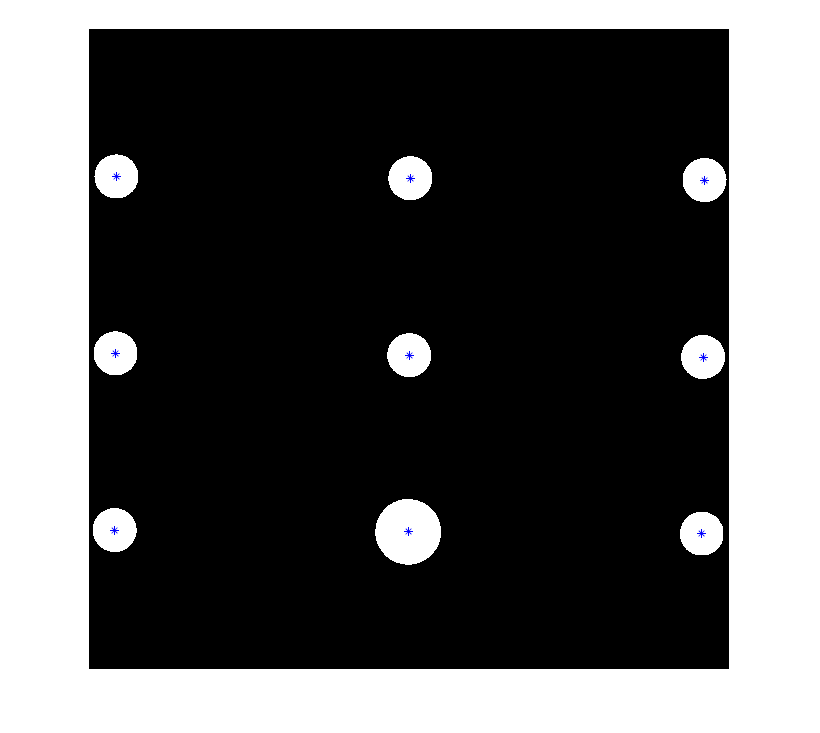

% Get colour plains
red = image(:,:,1);
green = image(:,:,2);
blue = image(:,:,3);

% Clean noise, Get blue circles
blueCircles = imclose(blue./(red+green+blue) > 0.6, ones(5,5));

% Get blue shapes' stats
blueStats = regionprops("table",blueCircles,"Centroid","Area","Circularity");
imshow(blueCircles)
hold on
plot(blueStats.Centroid(:,1),blueStats.Centroid(:,2),"b*")
hold off


% Store data
blueCentroids = cat(1,blueStats.Centroid);
blueAreas = cat(1,blueStats.Area);

% Left bottom circle = start circle
startCircleCentroid = [min(blueCentroids(:,1))+10 max(blueCentroids(:,2))-10]

startCircleCentroid =    36.1468  495.1290



i = [blueCentroids(:,1) < startCircleCentroid(1),  blueCentroids(:,2) > startCircleCentroid(2)]

i = 9×2 logical array
   1   1
   1   0
   1   0
   0   1
   0   0
   0   0
   0   1
   0   0
   0   0


i = i(:,1)+i(:,2)

i =      2
     1
     1
     1
     0
     0
     1
     0
     0


startPosition = find(i==2)

startPosition = 1


% Clone variable
centroidsNew = blueCentroids;
% Remove the largest circle
centroidsNew(startPosition,:) = [];
% 3rd column: Calculate and add distanceFromLargest circle
distanceFromLargest = [centroidsNew, sqrt(abs(centroidsNew(:,1)-blueCentroids(startPosition,1)).^2 + abs(centroidsNew(:,2)-blueCentroids(startPosition,2)).^2)];
% 4th column: Add sum of coordinates
distanceFromLargest = [distanceFromLargest, distanceFromLargest(:,1)+distanceFromLargest(:,2)];
% Sort in the ascending order of distanceFromLargest
distanceSorted = sortrows( distanceFromLargest, 3);
sorted3 = sortrows( distanceSorted(1:3,:), 4);
sorted5 = sortrows( distanceSorted(4:8,:), 4);
% Now put them in P, order is right as required
P = [blueCentroids(startPosition,1:2)' sorted3(:,1:2)' sorted5(:,1:2)' ; ones(1,9) ]

P =    26.1468   27.0450  320.7243  319.6776   27.8997  321.8077  615.9954  614.6128  613.2566
  501.5543  324.8029  326.6651  503.3634  147.9314  149.7218  151.5516  328.5010  505.1290
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


% The Euclidean workspace coordinates of the markers
Q = [ 20 182.5 182.5 20 345 345 345 182.5 20;  560 560 290 290 560 290 20 20 20;  ones(1,9) ]

Q =    20.0000  182.5000  182.5000   20.0000  345.0000  345.0000  345.0000  182.5000   20.0000
  560.0000  560.0000  290.0000  290.0000  560.0000  290.0000   20.0000   20.0000   20.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


H = simple_homography(P,Q)

H =     0.0057   -0.9186  480.5012
   -0.9177   -0.0070  586.2635
    0.0000   -0.0000    1.0000




% Get realworld initial coordinates
init_xy = zeros(2,3)

init_xy =      0     0     0
     0     0     0


init_xy_image = [init_xy_image;  ones(1,3)]

init_xy_image =   280.3724  144.8826  423.8615
  226.0782  210.5385  160.9014
    1.0000    1.0000    1.0000



temp_xy = H * init_xy_image(:,1)

temp_xy =   274.4276
  327.3953
    0.9991


init_xy(:,1) = temp_xy(1:2,:)./temp_xy(3,:)

init_xy =   274.6805         0         0
  327.6970         0         0



temp_xy = H * init_xy_image(:,2)

temp_xy =   287.9280
  451.8374
    0.9991


init_xy(:,2) = temp_xy(1:2,:)./temp_xy(3,:)

init_xy =   274.6805  288.1833         0
  327.6970  452.2381         0



temp_xy = H * init_xy_image(:,3)

temp_xy =   335.1195
  196.1774
    0.9994


init_xy(:,3) = temp_xy(1:2,:)./temp_xy(3,:)

init_xy =   274.6805  288.1833  335.3208
  327.6970  452.2381  196.2952
